# Fuel Economy Analysis

This demo is an example of performing data mining on historical fuel economy data. We have data from various cars built from year 2000 up to 2012.

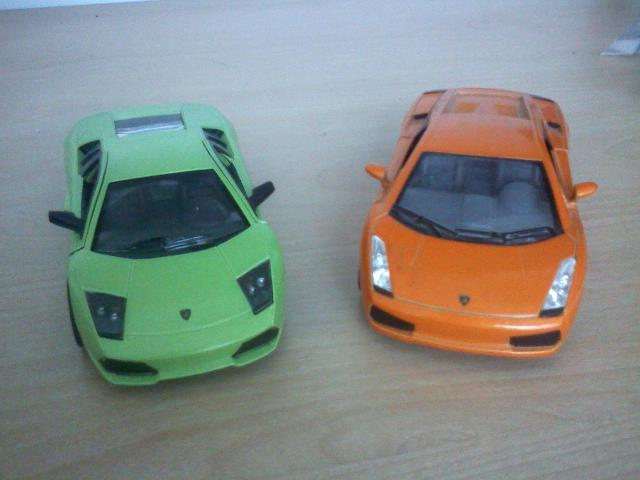

## Import Data into Table

Import from Excel using modified auto-generated function from Import Tool

carData = importYearXLS(2007);

## Visualize

Plot MPG versus Rated Horsepower

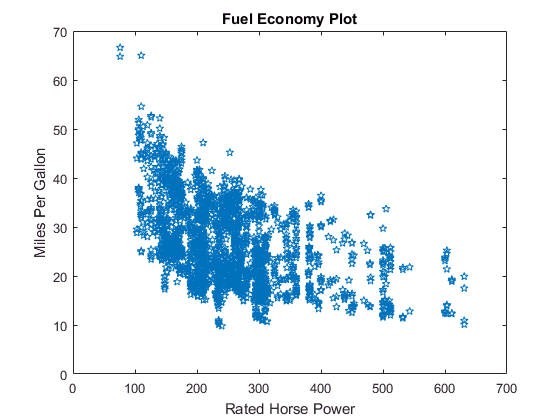

createMPGFigure(carData.RatedHP, carData.MPG);

## Examine Grouping Effects of Categorical Data

In order to extract all "cars":

carIDs = carData.Car_Truck == "car";

In order to extract "city" data for "trucks":

city_truckIDs = (carData.City_Highway == "city" & carData.Car_Truck == "truck");

City versus Highway

cityIDs = carData.City_Highway == "city";
highwayIDs = carData.City_Highway == "highway";

## Grouped Visualizations

Scatter plot by group.

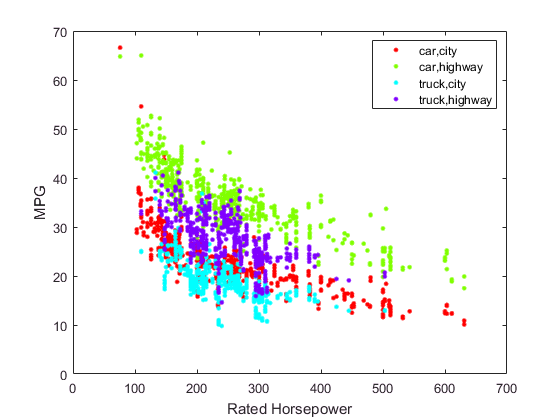

ans = 4×5 table
    City_Highway    Car_Truck    GroupCount    mean_RatedHP    mean_MPG
    ____________    _________    __________    ____________    ________
    city            car          672           253.17          22.693  
    city            truck        627           246.28          18.501  
    highway         car          671           251.09          35.542  
    highway         truck        625           246.76          27.459  

ans = 6×2 cell array
    'Source'                'Prob>F'     
    'Veh. Type'             [2.9814e-156]
    'MPG Type'              [          0]
    'Veh. Type*MPG Type'    [ 2.6038e-19]
    'Error'                            []
    'Total'                            []

figure
gscatter(carData.RatedHP, carData.MPG, ...
    {carData.Car_Truck, carData.City_Highway}, ...
    '', '.', 10, 'on', 'Rated Horsepower', 'MPG')

## Extract Data for Curve Fitting

Create these variables for Curve Fitting App

RatedHPCity = carData.RatedHP(cityIDs);
MPGCity     = carData.MPG(cityIDs);

% Use the App to develop a curve fit.

## Curve Fitting

Equation:


$$\mathrm{MPG}=b_1 +\frac{b_2 }{\mathrm{RatedHP}}$$


We can solve this using the Curve Fitting Tool

`cftool(carData.RatedHP, carData.MPG)`

The following is a modified version of the auto-generated m-file from `cftool`.

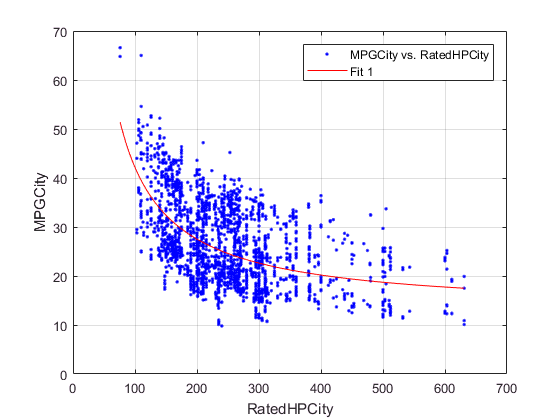

cf = createMPGFit(carData.RatedHP, carData.MPG);

## Plot Data and Model

The result from the Curve Fitting Toolbox has a `plot` method for displaying the result graphically. We can choose to display the prediction bounds for the fit.

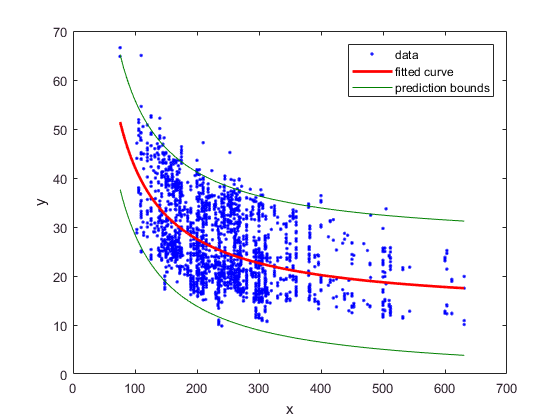

figure
hh = plot(cf, 'r', carData.RatedHP, carData.MPG, 'predobs', 0.95);
hh(2).LineWidth = 2;
for ii = [3 4]
    hh(ii).LineStyle = '-';
    hh(ii).Color = [0 0.5 0];
end

## Plot of Data and Model (for different groups)

We will apply the similar modeling technique to the data for different combinations of groups (Car-Truck and City-Highway)

Model different combinations:

mdl =      Linear model:
     mdl(x) = a + b*1/x
     Coefficients (with 95% confidence bounds):
       a =       10.12  (9.528, 10.72)
       b =        2663  (2546, 2779)

gof = struct with fields:
           sse: 5.6906e+03
       rsquare: 0.7496
           dfe: 670
    adjrsquare: 0.7493
          rmse: 2.9143

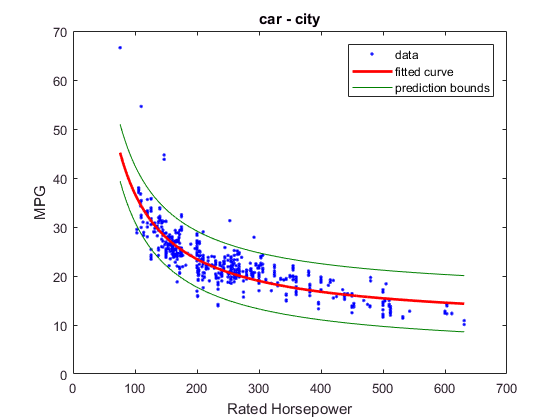

[mdl,gof] = modelMPG(carData, 'car', 'city')

ans =      Linear model:
     ans(x) = a + b*1/x
     Coefficients (with 95% confidence bounds):
       a =       21.33  (20.58, 22.09)
       b =        3005  (2857, 3153)

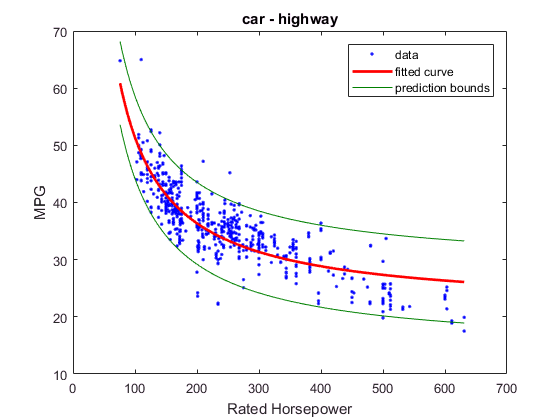

[mdl,gof] = modelMPG(carData, 'car', 'highway')

ans =      Linear model:
     ans(x) = a + b*1/x
     Coefficients (with 95% confidence bounds):
       a =       8.473  (7.579, 9.368)
       b =        2314  (2115, 2514)

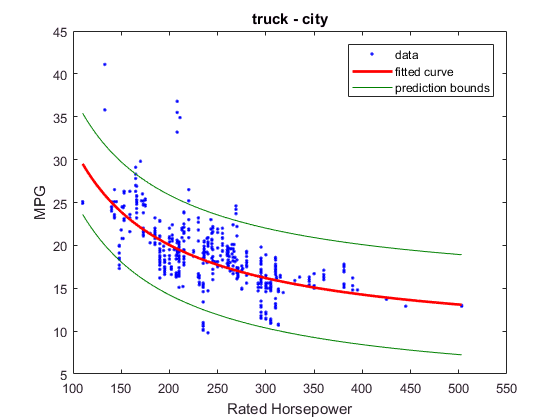

[mdl,gof] = modelMPG(carData, 'truck', 'city')

ans =      Linear model:
     ans(x) = a + b*1/x
     Coefficients (with 95% confidence bounds):
       a =       16.26  (15.11, 17.42)
       b =        2589  (2332, 2846)

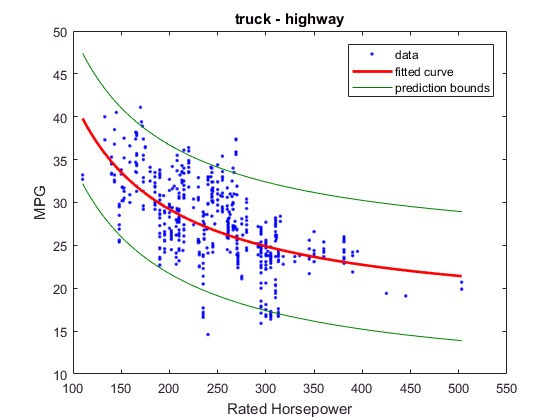

[mdl,gof] = modelMPG(carData, 'truck', 'highway')

*Copyright 2017 The MathWorks, Inc.*